clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

% Load Xband data
load('data/processed/sample4_20230512_mwpw.mat');
cwX = cw(4); % Mw power 0.1 mW
% Load Qband data
load('data/processed/sample4_20230622_Qband_mwpw.mat');
cwQ = cw(5); % Mw power 0.2 mW

# Fit

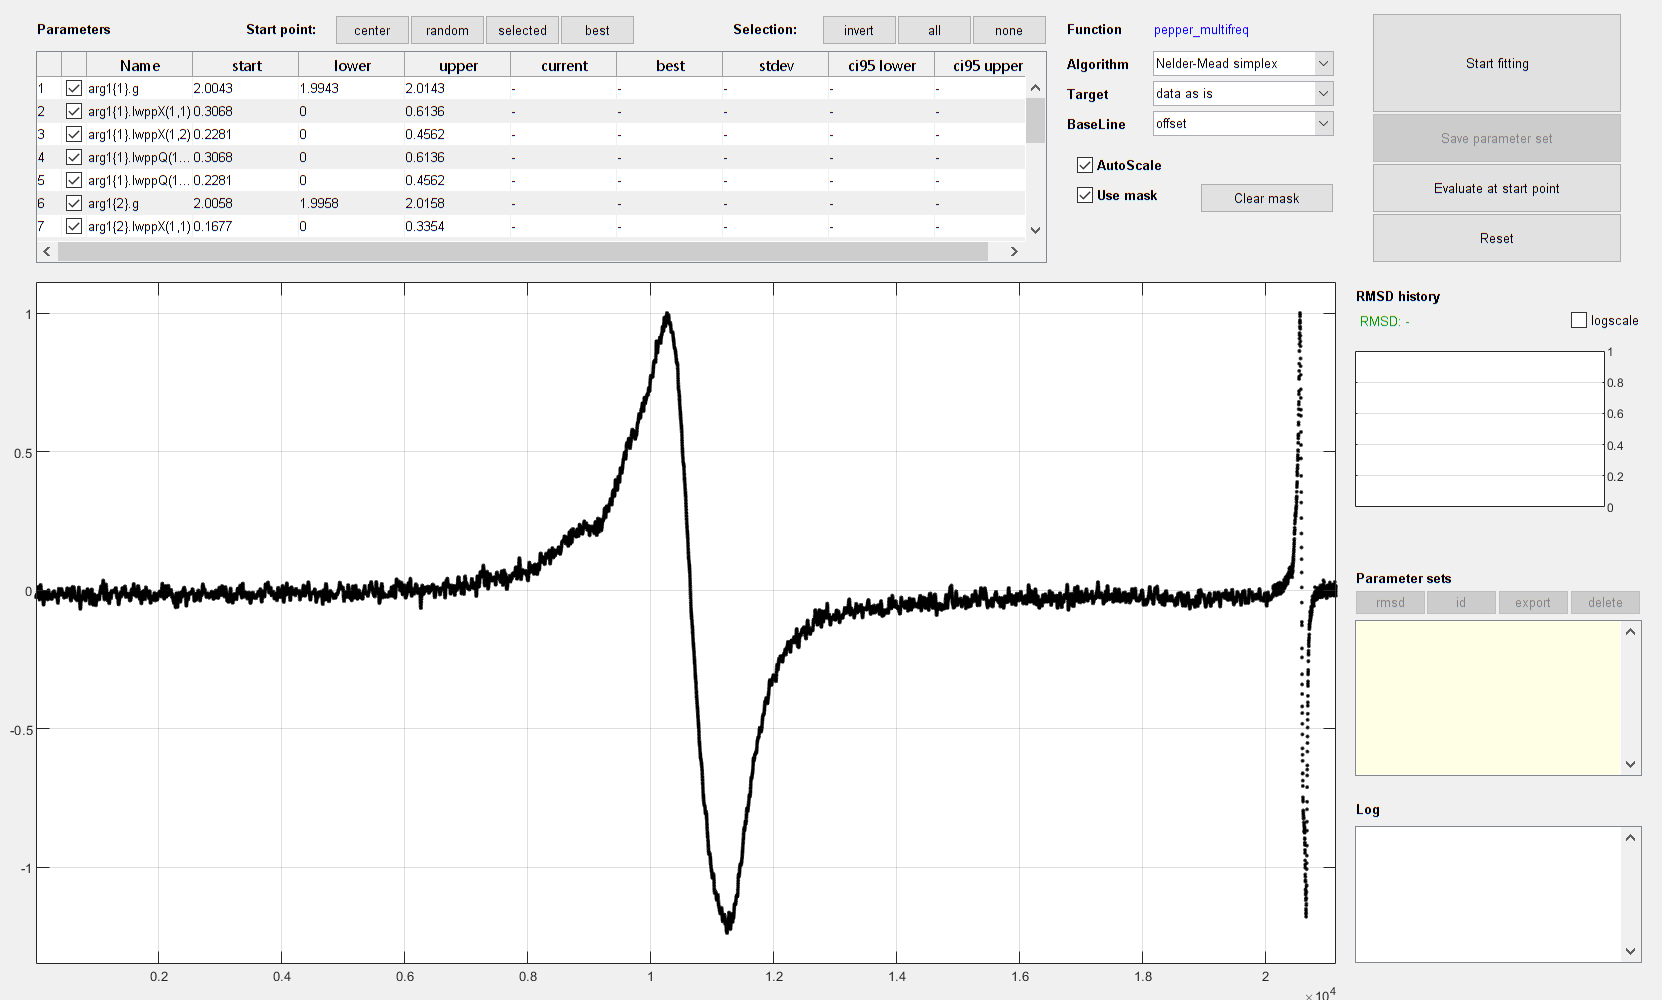

Sys0 = struct('g', 2.0043, ...
    'lwppX', [0.3068 0.2281], ...
    'lwppQ', [0.3068 0.2281]);
Sys1 = struct('g', 2.0058, ...
    'lwppX', [0.1677 0.3492], ...
    'lwppQ', [0.1677 0.3492], ...
    'weightX', 1.7510, ...
    'weightQ', 1.7510);
Sys2 = struct('g', 2.0077, ...
    'lwppX', [0.2251 0.8298], ...
    'lwppQ', [0.2251 0.8298], ...
    'weightX', 1.7510, ...
    'weightQ', 2.0587);

Vary0 = struct('g', .01, ...
    'lwppX', Sys0.lwppX, ...
    'lwppQ', Sys0.lwppQ);
Vary1 = struct('g', .01, ...
    'lwppX', Sys1.lwppX, ...
    'lwppQ', Sys1.lwppQ, ...
    'weightX', Sys2.weightX, ...
    'weightQ', Sys2.weightQ);
Vary2 = struct('g', .01, ...
    'lwppX', Sys2.lwppX, ...
    'lwppQ', Sys2.lwppQ, ...
    'weightX', Sys2.weightX, ...
    'weightQ', Sys2.weightQ);

% Exp
Exp.CenterSweepX = [mean(cwX.x) (max(cwX.x) - min(cwX.x))];
Exp.CenterSweepQ = [mean(cwQ.x) (max(cwQ.x) - min(cwQ.x))];
Exp.nPointsX = numel(cwX.x);
Exp.nPointsQ = numel(cwQ.x);
Exp.mwFreqX = cwX.Params.MwFreq;
Exp.mwFreqQ = cwQ.Params.MWFQ*1e-9;

% No printing
SimOpt.Verbosity = 0;

FitOpt.BaseLine = 0;

% Prepare x and y arrays for multifrequency
% Rescale
maxX = max(cwX.y);
yX = cwX.y/maxX;
maxQ = max(cwQ.y);
yQ = cwQ.y/maxQ;

% Store in custum field for rescaling in the custom 
% simulation function (e.g. pepper_multifreq)
Sys0.dataX = yX;
Sys0.dataQ = yQ;

% Combine datasets
y = [yX', yQ'];

esfit(y, @pepper_multifreq, {{Sys0, Sys1, Sys2}, Exp, SimOpt}, ...
    {{Vary0, Vary1, Vary2}}, FitOpt)

% mfesfit(X, Y, Sys0, Vary0, Exp)
% Fit = esfit(yy, @pepper, {Sys1, Exp}, {Vary1}, FitOpt);

Sys1f = struct('g', 2.0043, ...
    'lwpp', [0.3068 0.2281]);
Sys2f = struct('g', 2.0058, ...
    'lwpp', [0.1677 0.3492], ...
    'weight', 1.7510);
Sys4f = struct('g', 2.0077, ...
    'lwpp', [0.2251 0.8298], ...
    'weight', 2.0587);

figure()
plot(cw(ICW).x, cw(ICW).y)
hold on
Opt.Output = 'separate';
plot(cw(ICW).x, fit1.scale*pepper({Sys1f, Sys2f, Sys4f}, Exp, Opt))

function y = pepper_multifreq(Sys, Exp, SimOpt)
nSys = numel(Sys);

% Xband
for isys = 1:nSys
    Sys{isys}.lwpp = Sys{isys}.lwppX;
end
Exp.CenterSweep = Exp.CenterSweepX;
Exp.nPoints = Exp.nPointsX;
Exp.mwFreq = Exp.mwFreqX;

y = pepper(Sys, Exp, SimOpt);
yX = y/max(y);

% Qband
for isys = 1:nSys
    Sys{isys}.lwpp = Sys{isys}.lwppQ;
end
Exp.CenterSweep = Exp.CenterSweepQ;
Exp.nPoints = Exp.nPointsQ;
Exp.mwFreq = Exp.mwFreqQ;

y = pepper(Sys, Exp, SimOpt);
yQ = y/max(y);

yXref = Sys{1}.dataX;
yQref = Sys{1}.dataQ;

y = [rescaledata(yX,yXref,'lsq'), rescaledata(yQ,yQref,'lsq')];
end